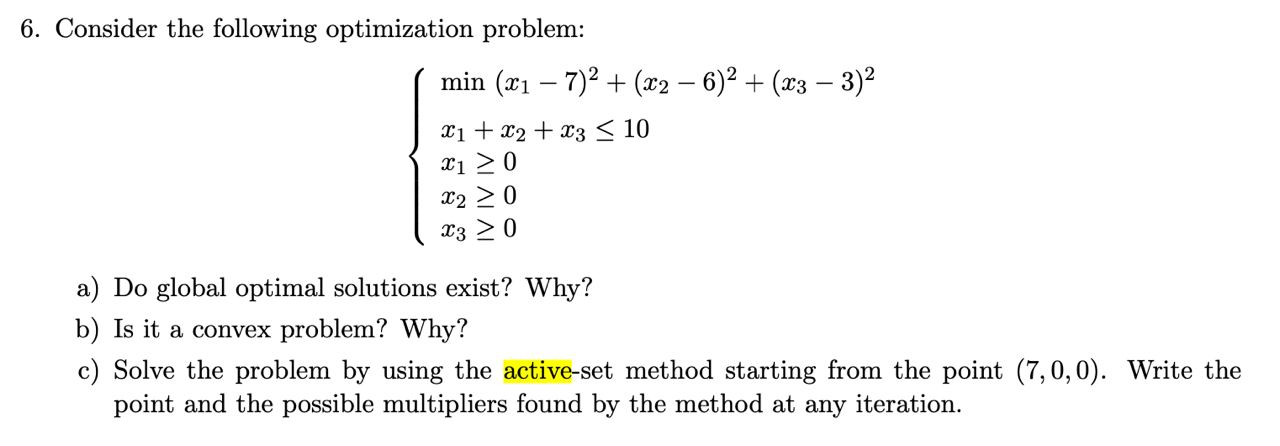

Q = [4 0 0
     0 4 0
     0 0 4];

eig(Q)

ans =      4
     4
     4



syms x1 x2 x3
objective_function = (x1 - 7)^2 + (x2 - 6)^2 + (x3 - 3)^2;

d_x1 = diff(objective_function, x1)

$$d\_x1 = 2\,x_{1}-14$$

d_x2 = diff(objective_function, x2)

$$d\_x2 = 2\,x_{2}-12$$

d_x3 = diff(objective_function, x3)

$$d\_x3 = 2\,x_{3}-6$$


dd_x1 = diff(d_x1, x1)

$$dd\_x1 = 2$$

dd_x2 = diff(d_x2, x2)

$$dd\_x2 = 2$$

dd_x3 = diff(d_x3, x3)

$$dd\_x3 = 2$$

dd_x1x2 = diff(dd_x1, x2)

$$dd\_x1x2 = 0$$

dd_x1x3 = diff(dd_x1, x3)

$$dd\_x1x3 = 0$$

dd_x2x3 = diff(dd_x2, x3)

$$dd\_x2x3 = 0$$



H = [dd_x1   dd_x1x2 dd_x1x3
     dd_x1x2 dd_x2   dd_x2x3
     dd_x1x3 dd_x2x3 dd_x2]

$$H = \left(\begin{array}{ccc} 2 & 0 & 0\\ 0 & 2 & 0\\ 0 & 0 & 2 \end{array}\right)$$


constraint_active= x1+x2+x3-10;
g_x1 = diff(constraint_active, x1)

$$g\_x1 = 1$$

g_x2 = diff(constraint_active, x2)

$$g\_x2 = 1$$

g_x3 = diff(constraint_active, x3)

$$g\_x3 = 1$$


$$\begin{array}{l}
0\le x_1 \le 10\\
0\le x_2 \le 10\\
0\le x_3 \le 10
\end{array}$$


Closed and bounded. Objective function continuous. Strongly convex



f1 = @(x1,x2,x3) (x1 - 7)^2 + (x2 - 6)^2 + (x3 - 3)^2;
c1=@(x1,x2,x3) x1+x2+x3-10; 
c2=@(x1,x2,x3) -x1;
c3=@(x1,x2,x3) -x2;
c4=@(x1,x2,x3) -x3;

x1 = linspace(0,10, 100);
x2 = linspace(0,10, 100);
x3 = linspace(0,10, 100);

[X1,X2,X3] = meshgrid(x1,x2,x3);

C1 = c1(x1,x2,x3) == 0;
C2 = c2(x1,x2,x3) == 0;
C3 = c3(x1,x2,x3) == 0;
C4 = c4(x1,x2,x3) == 0;


% Constraints Satisfy

x1 = 7;
x2 = 0;
x3 = 0;

C1 = c1(x1,x2,x3) <= 0

C1 = logical
   1


C2 = c2(x1,x2,x3) <= 0

C2 = logical
   1


C3 = c3(x1,x2,x3) <= 0

C3 = logical
   1


C4 = c4(x1,x2,x3) <= 0

C4 = logical
   1




% 1 Satisfy 0 Non-Satisfy

F1 = f1(x1,x2,x3) 

F1 = 45

syms x1 x2 x3 lambda1 lambda2 lambda3

d = [d_x1 
     d_x2
     d_x3];

p = [g_x1
     g_x2
     g_x3]

$$p = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$


lagrangian = [d(1) + lambda1*p(1)
              d(2) + lambda2*p(2)
              d(3) + lambda3*p(3)]

$$lagrangian = \left(\begin{array}{c} \lambda_{1}+2\,x_{1}-14\\ \lambda_{2}+2\,x_{2}-12\\ \lambda_{3}+2\,x_{3}-6 \end{array}\right)$$


equations = [lagrangian == 0
             constraint_active <= 0
             lambda1*(constraint_active) == 0
             lambda1 >= 0]

$$equations = \left(\begin{array}{c} \lambda_{1}+2\,x_{1}-14=0\\ \lambda_{2}+2\,x_{2}-12=0\\ \lambda_{3}+2\,x_{3}-6=0\\ x_{1}+x_{2}+x_{3}-10\leq 0\\ \lambda_{1}\,\left(x_{1}+x_{2}+x_{3}-10\right)=0\\ 0\leq \lambda_{1} \end{array}\right)$$




solution = solve(equations)

solution = struct with fields:
    lambda1: 0
    lambda2: 12
    lambda3: 6
         x1: 7
         x2: 0
         x3: 0


d = [double(subs(d_x1,7))
     double(subs(d_x2,0))
     double(subs(d_x3,0))]

d =      0
   -12
    -6



p = [double(subs(g_x1,7))
     double(subs(g_x2,0))
     double(subs(g_x3,0))]

p =      1
     1
     1



lagrangian = sum(d)

lagrangian = -18